# Proyecto Final

Obtiene todas las imágenes de cada clase del directorio *Objetos_segmentados*

[imageClasses,labelMap] = ImageProcessing.getImagesClasses("Objetos_segmentados");

Se muestra la imagen 8 de la séptima clase

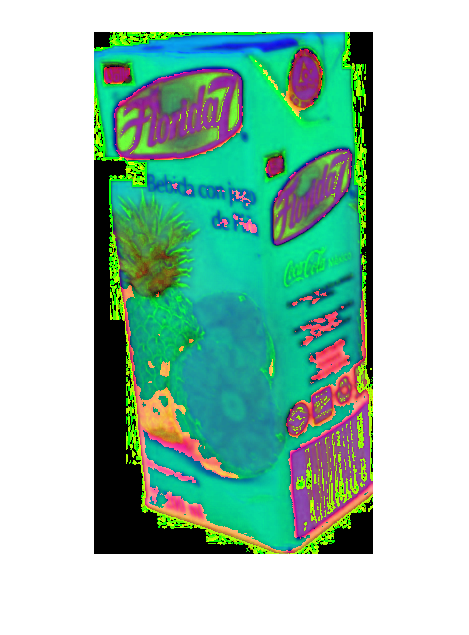

imshow(rgb2hsv(imageClasses{7}{8}))

Se muestran las propiedades de labelMap y un ejemplo de su uso

labelMap

labelMap =   Map with properties:

        Count: 10
      KeyType: double
    ValueType: char


fprintf('A la clase %d le pertence la etiqueta %s',1,labelMap(1));

A la clase 1 le pertence la etiqueta appleJuice

Divide a las imágenes en datos de entreneamiento y datos de prueba

images_train = cellfun(@(imageClass) imageClass(1:15), imageClasses, 'UniformOutput', false);
images_test = cellfun(@(imageClass) imageClass(16:end), imageClasses, 'UniformOutput', false);

Obtiene los canales HSV de la muestra 8 de la clase 7 para desplegarlos

images_train_HSV = cellfun(@rgb2hsv, images_train{7}, 'UniformOutput', false)

images_train_HSV = 1×15 cell array
    {493×215×3 double}    {436×211×3 double}    {362×180×3 double}    {364×184×3 double}    {482×239×3 double}    {559×279×3 double}    {504×250×3 double}    {522×279×3 double}    {468×240×3 double}    {430×187×3 double}    {437×175×3 double}    {424×195×3 double}    {394×231×3 double}    {433×214×3 double}    {468×211×3 double}


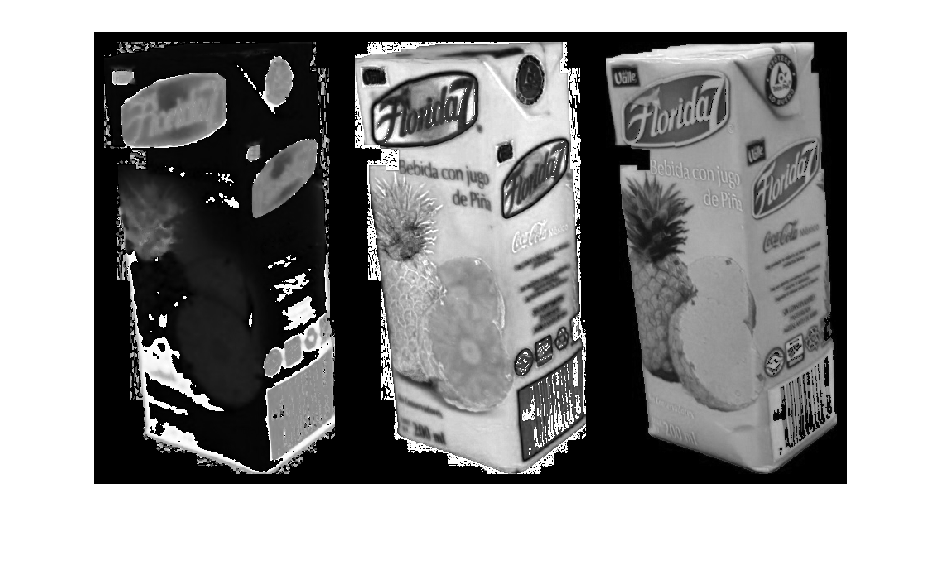

[h s v] = imsplit(images_train_HSV{8});
montage({h, s, v}, 'BorderSize', 10);

Despliegue de la imagen aplicando filtros de sobel verticales

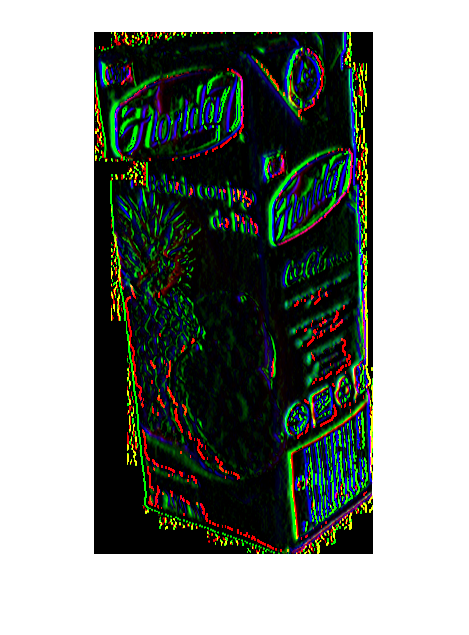

test = ImageProcessing.filter(images_train_HSV{8});
img = cat(3,test(:,:,4),test(:,:,5),test(:,:,6));
imshow(img)

Para cada clase de imagenes se obtiene su cuantizador vectorial

sizeQuantizer = 16; % Tamaño de los cuantizadores vectoriales
vecQuantizers = {}; % Cell array para almacenar a los cuantizadores vectoriales
for i = 1:length(images_train)
  images_scaled = cellfun(@(image) imresize(image,0.5), images_train{i}, 'UniformOutput', false );
  images_HSV = cellfun(@rgb2hsv, images_scaled, 'UniformOutput', false);
  images_filtered = cellfun(@ImageProcessing.filter, images_HSV, 'UniformOutput', false);
  pixels = ImageProcessing.imgClass2matrix(images_filtered);
  C1 = 1/length(pixels) *sum(pixels);
  [idx, C] = CuantizadorVectorial.LindeBuzoGray(C1,sizeQuantizer,double(pixels));
  vecQuantizers{i} = {idx, C};
end

Se verifican los centroides obtenidos, así como la cantidad de elementos que contiene cada grupo en el cuantizador vectorial de la clase appleJuice.

idx_1 = vecQuantizers{1}{1}; %Índices asignados a cada pixel de la clase appleJuice
C_1 = vecQuantizers{1}{2} %Centroides del cuantizador de la clase appleJuice

C_1 =

    0.0877    0.1694    0.3031   -0.0253    0.0037    0.0063   -0.0446   -0.0287   -0.0592
    0.5319    0.4254    0.4126   -0.0048    0.0477   -0.0101   -0.0237    1.0975   -0.3485
    0.5178    0.3568    0.3808   -1.9593   -0.2371    0.0551    0.9747    0.1124   -0.0271
    0.5971    0.4338    0.4018    0.0249    1.2121   -0.4615    0.0055   -0.0589    0.0236
    0.5667    0.4083    0.4145   -0.0536   -1.0357    0.4190   -0.0362   -0.1529    0.0445
    0.5338    0.2537    0.4278    0.3637    0.0490   -0.0330    1.0938   -0.0441    0.0166
    0.4866    0.4679    0.3408   -0.0365   -0.0324   -0.0014   -0.3455   -1.7614    0.3182
    0.5287    0.3287    0.4230    1.8870    0.2426   -0.0860   -0.9789   -0.1806    0.0314
    0.6970    0.4084    0.4731   -0.0154    0.0080   -0.0017   -0.0212   -0.0317    0.0488
    0.4587    0.4395    0.1550    0.0519    0.0961    0.0006    1.3402    2.6012   -0.2743
    0.5398    0.4207    0.3395   -3.0670   -0.5606   -0.1679   -0.9375   -0.1792   

for i=1:sizeQuantizer
  fprintf('Centroide: %d  Elementos: %d\n',i,numel(find(idx_1 == i)))
end

Centroide: 1  Elementos: 50322
Centroide: 2  Elementos: 19991
Centroide: 3  Elementos: 9099
Centroide: 4  Elementos: 18867
Centroide: 5  Elementos: 20396
Centroide: 6  Elementos: 13691
Centroide: 7  Elementos: 13227
Centroide: 8  Elementos: 10113
Centroide: 9  Elementos: 100899
Centroide: 10  Elementos: 6324
Centroide: 11  Elementos: 7173
Centroide: 12  Elementos: 4678
Centroide: 13  Elementos: 5620
Centroide: 14  Elementos: 5765
Centroide: 15  Elementos: 9612
Centroide: 16  Elementos: 6552


Clasificación de las imagenes de entrenamiento

disp('Clasificando las imágenes de entrenamiento')

Clasificando las imágenes de entrenamiento


La clasificación para las imágenes de la clase 1 (appleJuice) fue:
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1

La clasificación para las imágenes de la clase 2 (blueBowl) fue:
     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2

La clasificación para las imágenes de la clase 3 (blueLego) fue:
     3     3     3     3     3     3     3     3     3     2     5     3     3     3     3

La clasificación para las imágenes de la clase 4 (blueMug) fue:
     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4

La clasificación para las imágenes de la clase 5 (blueSpoon) fue:
     5     2     2     2     2     2     5     5     5     5     5     5     3     3     2

La clasificación para las imágenes de la clase 6 (chocolateCookies) fue:
     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6

La clasificación para las imágenes de la clase 7

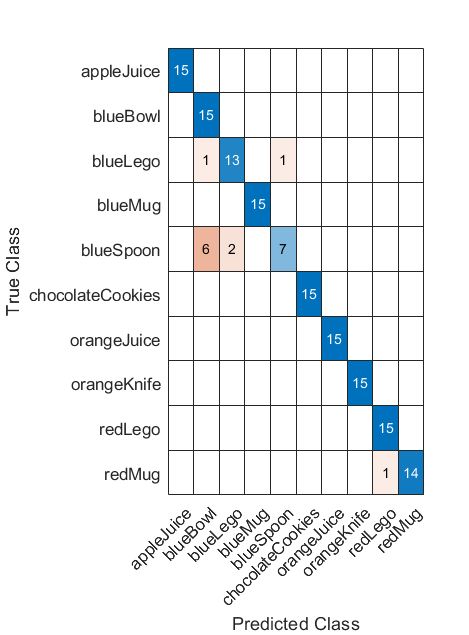

clasificacionCuantVect(images_train,vecQuantizers,labelMap)

Clasificación de las imagenes de prueba

disp('Clasificando las imágenes de prueba')

Clasificando las imágenes de prueba


La clasificación para las imágenes de la clase 1 (appleJuice) fue:
     1     1     1     1     1

La clasificación para las imágenes de la clase 2 (blueBowl) fue:
     2     2     2     2     2

La clasificación para las imágenes de la clase 3 (blueLego) fue:
     3     3     3     3     3

La clasificación para las imágenes de la clase 4 (blueMug) fue:
     4     4     3     3     4

La clasificación para las imágenes de la clase 5 (blueSpoon) fue:
     5     5     5     2     5

La clasificación para las imágenes de la clase 6 (chocolateCookies) fue:
     6     6     6     6     6

La clasificación para las imágenes de la clase 7 (orangeJuice) fue:
     7     7     7     7     7

La clasificación para las imágenes de la clase 8 (orangeKnife) fue:
     8     8     8     8     8

La clasificación para las imágenes de la clase 9 (redLego) fue:
     9     9     9     9     9

La clasificación para las imágenes de la clase 10 (redMug) fue:
    10     9    10    10    10



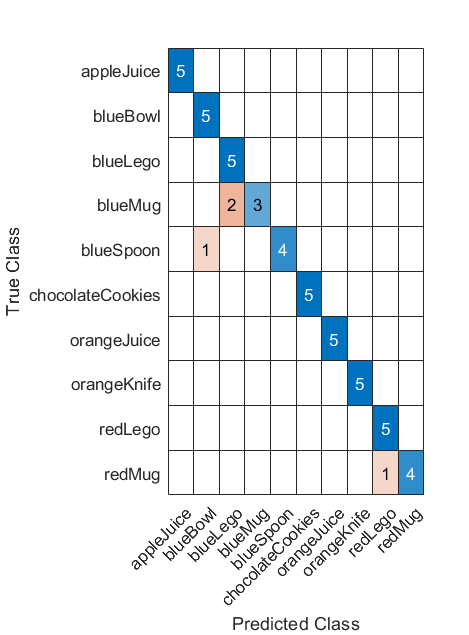

clasificacionCuantVect(images_test,vecQuantizers,labelMap)

**Clasificación de imágenes mediante cuantización vectorial**

Función para clasificar las imagenes, ya sea de entrenamiento o de prueba mediante la tecnica de cuantización vectorial.

Al final muestra su matriz de confusión.

function clasificacionCuantVect(imgClass,quantizers,labelMap)
  prediction = double.empty; % Valores que el clasificador predice
  actual = double.empty; % Valores reales
  
  for i=1:length(imgClass) % Itera sobre las clases
    nImgs = length(imgClass{i});
    clasifications = zeros(1,nImgs);
    for j=1:nImgs % Itera sobre las imágenes de la clase iésima
      % Obtiene los pixeles de la imagen
      image_scaled = imresize(imgClass{i}{j},0.5);
      image_HSV = rgb2hsv(image_scaled);
      image_filtered = ImageProcessing.filter(image_HSV);
      pixels = ImageProcessing.img2matrix(image_filtered);
      % Obtiene la clasificación de la imagen de acuerdo a su distancia
      % mínima a cada cuantizador
      clasifications(j) = CuantizadorVectorial.clasificador(double(pixels),quantizers);
    end
    prediction = [prediction,clasifications];
    actual = [actual,ones(1,nImgs)*i];
    fprintf('La clasificación para las imágenes de la clase %d (%s) fue:\n',i,labelMap(i));
    disp(clasifications)
  end
  
  
  % Obtiene las etiquetas de los valores reales y predichos
  labelActual = arrayfun(@(num) labelMap(num),actual,'UniformOutput',false);
  labelPred = arrayfun(@(num) labelMap(num),prediction,'UniformOutput',false);
  % Genera una matriz de confusión y las muestra
  confusionchart(labelActual,labelPred)
end